Kernel is defined as


$$K \equiv \{g \in G | \Phi(g)=e^{'}\}$$


In words, K is the set of all elements of G that get sent to $e^{'}$ under $\Phi$


$$1=\pmatrix{1 &0 \cr 0 &1}$$
 
$$\sigma_1=\pmatrix{0 &1 \cr 1 &0}$$
 
$$\sigma_2=\pmatrix{0 &-i \cr i &0}$$
 
$$\sigma_3=\pmatrix{1 &0 \cr 0 &-1}$$


Every SO(3) matrix can be represented by 2 SU(2) matrices since acting anti-Hermitian 2*2 matrices by SU(2) is homomorphic to acting 3*1 vector by SO(3) matrices and SU(2) have 2 operators which does nothing at all while SO(3) has one, we call SU(2) as double cover of SO(3). Anti-Hermitian 2*2 matrices and 3*1 real vectors both have 3 independent variables.

Rotation with SU(2) defined as


$$(SU)(AH)(SU)^\dagger$$


while rotation with SO(3) defined as


$$(SO3)V$$



$$K=\{I,-I\}$$


Isometry group: The group that not change inner product

$O(n), U(n)$and $O(n-1,1)$are isometry groups

Euclidean inner product:


$$(v|w)=v^Tw$$


Hermitian inner product:


$$(v|w)=v^{\dagger}w$$
 

Minkowski inner product:


$$(v|w)=v^T\eta w$$


Some useful relations:


$$A=B \rightarrow det(A)=det(B)$$


 
$$det(AB)=det(A)det(B)$$


 
$$det(A^T)=det(A)$$



$$det(A^{-1})=\frac{1}{det(A)}$$



$$det(AXA^{-1})=det(X)$$



$$det(e^X)=e^{Tr X}$$



$$e^{AXA^{-1}}=Ae^XA^{-1}$$


- 
$$O(n):$$


$O(n)$ is the group that leaves Euclidean inner product invariant:

        
$$(Ov|Ow)=(v|w) \rightarrow v^TO^TOw=v^Tw \rightarrow O^TO=I$$


Since $A=B \rightarrow det(A)=det(B)$, $det(AB)=det(A)det(B)$ and $det(A^T)=det(A)$

        
$$det(O^T)det(O)=det(I) \rightarrow det(O)=\pm 1$$


An arbitrary member of $O(n)$is $O=e^{tX}$ so 

        
$$(e^{tX})^T e^{tX}=I \rightarrow e^{tX^T}e^{tX}=I \rightarrow X^T = -X$$


Thus, the Lie algebra of $O(n)$ is the set of $n \times n$ antisymmetric matrices.

- 
$$SO(n):$$


$O(n)$ with $det(O)=1$

        
$$det(e^{tX})=e^{Tr X}=1 \rightarrow Tr X=0$$
 

        We already knew that $so(n)$is traceless since it is antisymmetric

$SO(n)$ are $n \times n$ real matrices and act on $n \times 1$ vectors:

        
$$Sv=S_\mu^{\ \nu}v_\nu$$


- 
$$U(n):$$


$U(n)$ is the group that leaves Hermitian inner product invariant:

        
$$(Uv|Uw)=(v|w) \rightarrow v^{\dagger}U^{\dagger}Uw=v^{\dagger}w \rightarrow U^{\dagger}U=I$$


Since $A=B \rightarrow det(A)=det(B)$, $det(AB)=det(A)det(B)$ and $det(A^\dagger)=det(A)$

        
$$det(U^\dagger)det(U)=det(I) \rightarrow det(U)=\pm 1$$


An arbitrary member of $U(n)$ is $U=e^{tX}$ so 

        
$$(e^{tX})^{\dagger} e^{tX}=I \rightarrow e^{tX^{\dagger}}e^{tX}=I \rightarrow X^{\dagger} = -X$$


Thus, the Lie algebra of $U(n)$ is the set of $n \times n$ anti-Hermitian matrices.

$v_{\mu \nu}=U_\mu^{\ \alpha} \ U_\nu^{\ \beta} \ v_{\alpha \beta}$  , since $U_\nu^{\ \beta} \ v_{\alpha \beta}=U_\nu^{\ \beta} \ v_{\beta \alpha }^\dagger =U v^\dagger$ we conclude this is equal to $v^{'}=UvU^\dagger$

- 
$$SU(n):$$


$U(n)$ with $det(U)=1$

        
$$det(e^{tX})=e^{Tr X}=1 \rightarrow Tr X=0$$
 

        So, $su(n)$ is traceless in addition to being anti-Hermitian

- 
$$O(n-1,1):$$


$O(n-1,1)$ is the group that leaves Minkowski inner product invariant:

        
$$(\Lambda v|\Lambda w)=(v|w) \rightarrow v^T \Lambda^T \eta \Lambda w=v^T \eta w \rightarrow \Lambda^T \eta \Lambda=\eta$$


Since $A=B \rightarrow det(A)=det(B)$, $det(AB)=det(A)det(B)$ and $det(A^T)=det(A)$

        
$$det(\Lambda^T)det(\eta)det(\Lambda)=det(\eta) \rightarrow det(\Lambda^T)(-1)det(\Lambda)=-1 \rightarrow det(\Lambda)=\pm 1$$


An arbitrary member of $O(n-1,1)$ is $O=e^{tX}$ so

        
$$e^{tX^T}\eta e^{tX}=\eta \rightarrow \frac{d}{dt}(e^{tX^T}\eta e^{tX})=\frac{d}{dt}(\eta) \rightarrow X^T e^{tX^T}\eta e^{tX} + e^{tX^T}\eta X e^{tX}=0$$


and since $e^{tX^T}\eta e^{tX}=\eta$ and $[X,e^{tX}]=0$

        
$$X^T \eta + \eta X=0 \rightarrow X^T \eta = -\eta X$$



$$so(2):$$



$$s^T=-s$$


syms s  [2 2] real
syms t

eqn=transpose(s)==-s;
sol=solve(eqn,'ReturnConditions',true);
s=[sol.s1_1 sol.s1_2;sol.s2_1 sol.s2_2];
s=subs(s,sol.parameters,1)
R=simplify(expm(t*s))
[X Y]=meshgrid(-1:.1:1);
Xtemp=X;
Ytemp=Y;
X=X(Xtemp.^2+Ytemp.^2<=1);
Y=Y(Xtemp.^2+Ytemp.^2<=1);

U=s*[X';Y'];
quiver(X',Y',U(1,:),U(2,:))


$$so(3):$$



$$[J_i,J_j]=i \epsilon_{ijk}J_k$$


syms s  [3 3] real
syms t

eqn=transpose(s)==-s;
sol=solve(eqn,'ReturnConditions',true);
s=[sol.s1_1 sol.s1_2 sol.s1_3;
   sol.s2_1 sol.s2_2 sol.s2_3;
   sol.s3_1 sol.s3_2 sol.s3_3]

$$s = \left(\begin{array}{ccc} 0 & -x & -y\\ x & 0 & -u\\ y & u & 0 \end{array}\right)$$


Lx=subs(s,sol.parameters,[1 zeros(1,2)])

$$Lx = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0 \end{array}\right)$$

Ly=subs(s,sol.parameters,[zeros(1,2) -1])

$$Ly = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 0 & 0\\ -1 & 0 & 0 \end{array}\right)$$

Lz=subs(s,sol.parameters,[0 1 0])

$$Lz = \left(\begin{array}{ccc} 0 & -1 & 0\\ 1 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

[X Y Z]=sphere(10);
% Xtemp=X;
% Ytemp=Y;
% Ztemp=Z;
% X=X(Xtemp.^2+Ytemp.^2+Ztemp.^2<=1);
% Y=Y(Xtemp.^2+Ytemp.^2+Ztemp.^2<=1);
% Z=Z(Xtemp.^2+Ytemp.^2+Ztemp.^2<=1);

com=(Lx*Ly-Ly*Lx)

$$com = \left(\begin{array}{ccc} 0 & -1 & 0\\ 1 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

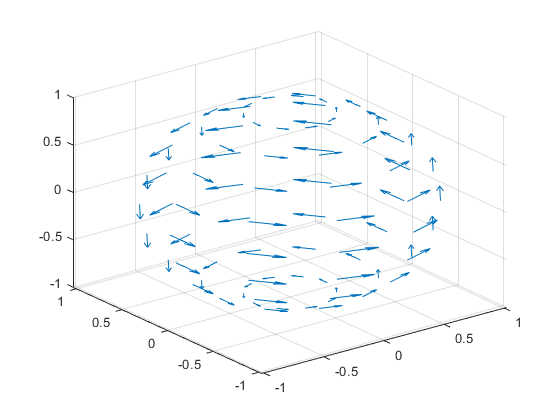


U=com*[X(:)';Y(:)';Z(:)'];
U1=double(U(1,:));
U2=double(U(2,:));
U3=double(U(3,:));
%quiver3D([X(:),Y(:),Z(:)],[U1(:),U2(:),U3(:)]);
quiver3(X(:)',Y(:)',Z(:)',U(1,:),U(2,:),U(3,:))
hold off


$$su(2):$$


syms su [2 2]

%traceless
su(1,1)=-su(2,2);
eqn=su'==-su

$$eqn = \left(\begin{array}{cc} -\bar{{\mathrm{su}}_{2,2}}={\mathrm{su}}_{2,2} & \bar{{\mathrm{su}}_{2,1}}=-{\mathrm{su}}_{1,2}\\ \bar{{\mathrm{su}}_{1,2}}=-{\mathrm{su}}_{2,1} & \bar{{\mathrm{su}}_{2,2}}=-{\mathrm{su}}_{2,2} \end{array}\right)$$

sol=solve(eqn,'ReturnConditions',true)

sol = struct with fields:
         su1_2: [1×1 sym]
         su2_1: [1×1 sym]
         su2_2: [1×1 sym]
    parameters: [1×2 sym]
    conditions: [1×1 sym]


s=[-sol.su2_2 sol.su1_2;sol.su2_1 sol.su2_2]

$$s = \left(\begin{array}{cc} -x\,\mathrm{i} & z\\ -\bar{z} & x\,\mathrm{i} \end{array}\right)$$

[sol.parameters sol.conditions]

$$ans = \left(\begin{array}{ccc} x & z & x\in \mathbb{R} \end{array}\right)$$

s1=diff(s,sol.parameters(1))

$$s1 = \left(\begin{array}{cc} -\mathrm{i} & 0\\ 0 & \mathrm{i} \end{array}\right)$$

s2=-diff(s,sol.parameters(2))

$$s2 = \left(\begin{array}{cc} 0 & -1\\ 1 & 0 \end{array}\right)$$


$$gl(V):$$


Let $V$ be a (possibly infinite-dimensional) vector space. We can turn $L(V)$, the set of all linear operators on $V$ , into a Lie algebra by taking the Lie bracket to be the commutator, i.e.


$$[T,U]=TU-UT$$


Note that this is a commutator of operators, not matrices, though of course there is a nice correspondence between the two when $V$ is finite-dimensional and we introduce a basis.


$$isom(V):$$


$gl(V)$ with $T^\dagger=-T$